# Classifying ECG Signals (Part 1 - CNNs)

We will use deep learning to classify the same ECG dataset using two techniques:

- CNN - Convolutional Neural Network

- LSTM - Long Short-Term Memory Network

## Access and View the Dataset

The networks we train will detect whether an echocardiogram (ECG) signal comes from a heart with: 

- *Normal Sinus Rhythm (NSR)*

- * Arrythmia (ARR) *

- *Congestive Heart Failure (CHF)*

The data are 162 sample signals, sampled at a frequency (Fs) of 128Hz.

load('ECGData.mat')

subplot(3,1,1); plot(Normal_Sample); title('NSR')
subplot(3,1,2); plot(Arrythmia_Sample); title('ARR')
subplot(3,1,3); plot(HeartFailure_Sample); title('CHF')

## Preprocess Data for CNN

To train a CNN, we first have to convert our signals into images that exhibit unique characteristics for each class. One approach that works for this data set is to convert the data to the time-frequncy spectrum using [continuous wavelet transform](https://www.mathworks.com/help/wavelet/gs/continuous-wavelet-transform-and-scale-based-analysis.html).

% Use the drop down to change the condition
sampleCondition = HeartFailure_Sample;
cwt(sampleCondition)

Open the [`PrepareSignalData.mlx`](matlab:edit('PrepareSignalData.mlx');) file.  This script applies the continuous wavelet transform to all the siganls and saves the images in 'data' folder. This step has already been done, so **you do not run the script**. 

% edit PrepareSignalData.mlx

## View Processed Data

filePath = fullfile('6-SignalClassificationECG', '6-Wavelets');
imds = imageDatastore(filePath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

heartRhythm = "CHF";
idx = find(string(imds.Labels) == heartRhythm);

for i = 1:4
    selectIdx = idx(randi(numel(idx)));
    im = imread(imds.Files{selectIdx});
    subplot(2,2,i)
    imshow(im)
    title(string(imds.Labels(selectIdx)));
end

## Split Data into Training and Test Images

[trainingImages, testImages] = splitEachLabel(imds, 0.8, 'randomize');

## Build CNN with Transfer Learning

deepNetworkDesigner

## **Step 1: Import SqueezeNet**

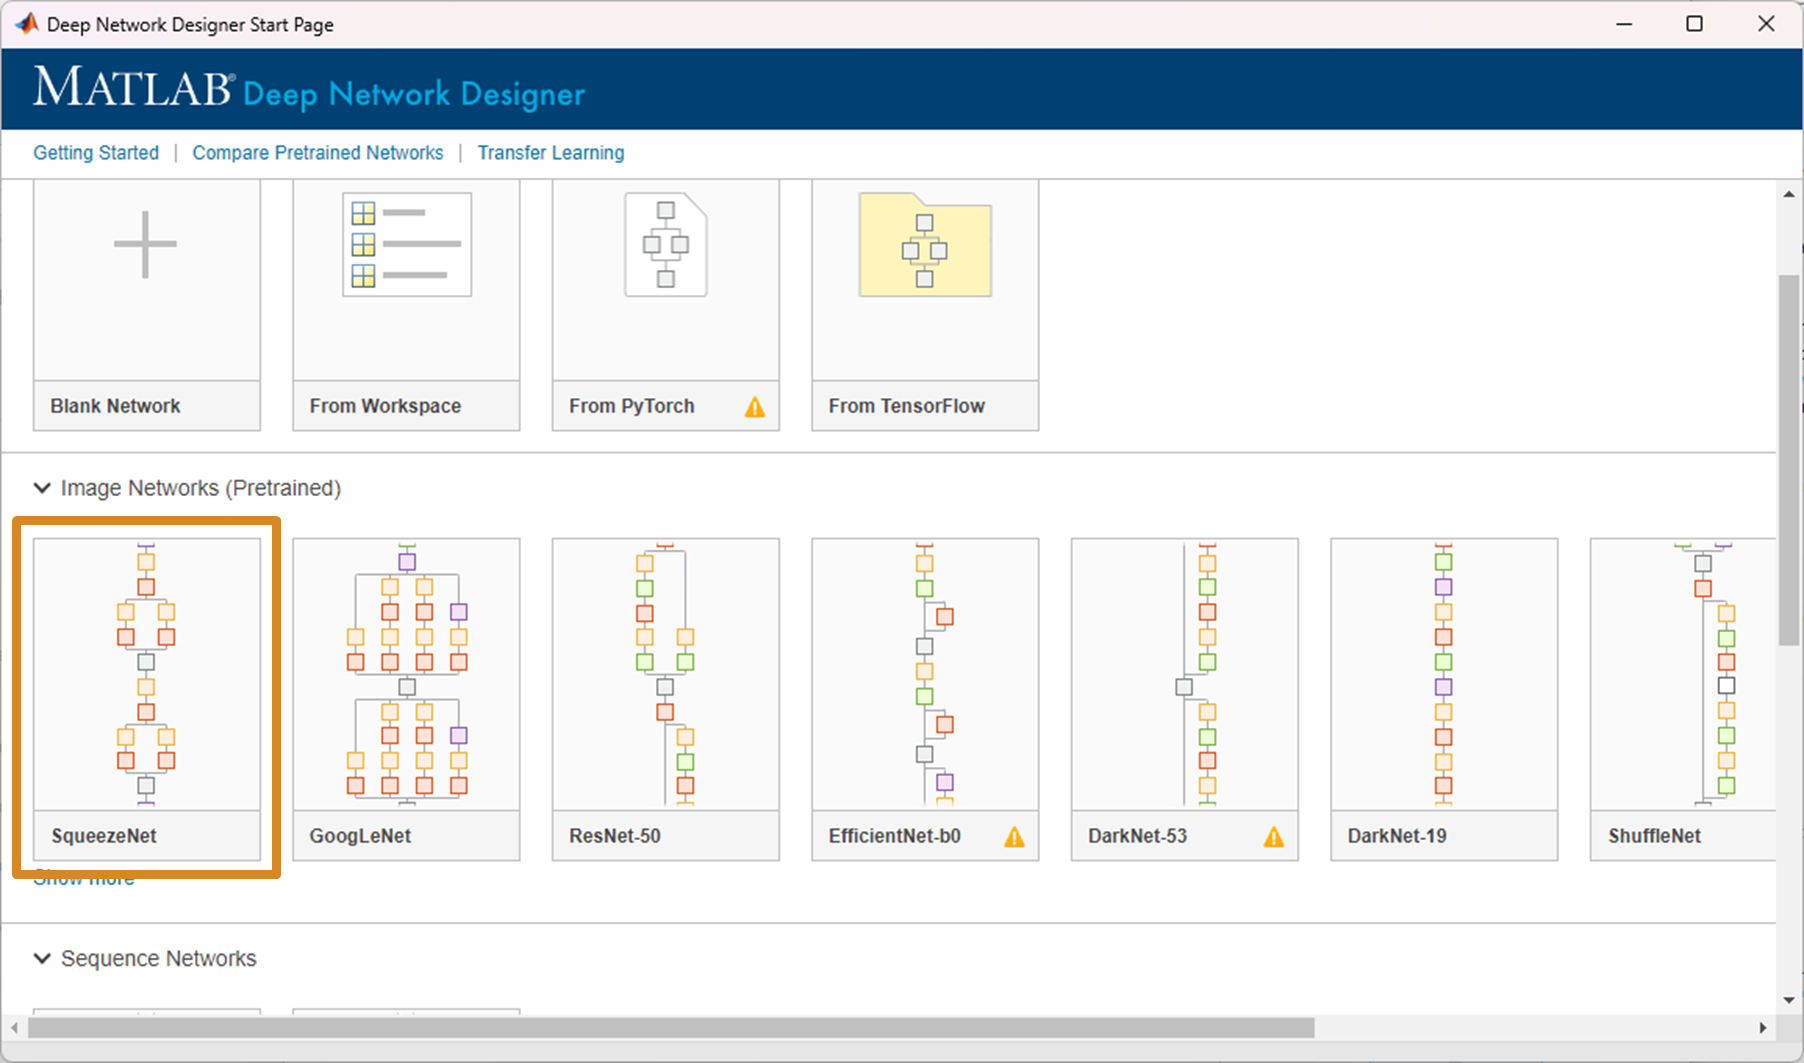

## **Step 2: Replace last learnable layer with new layer**

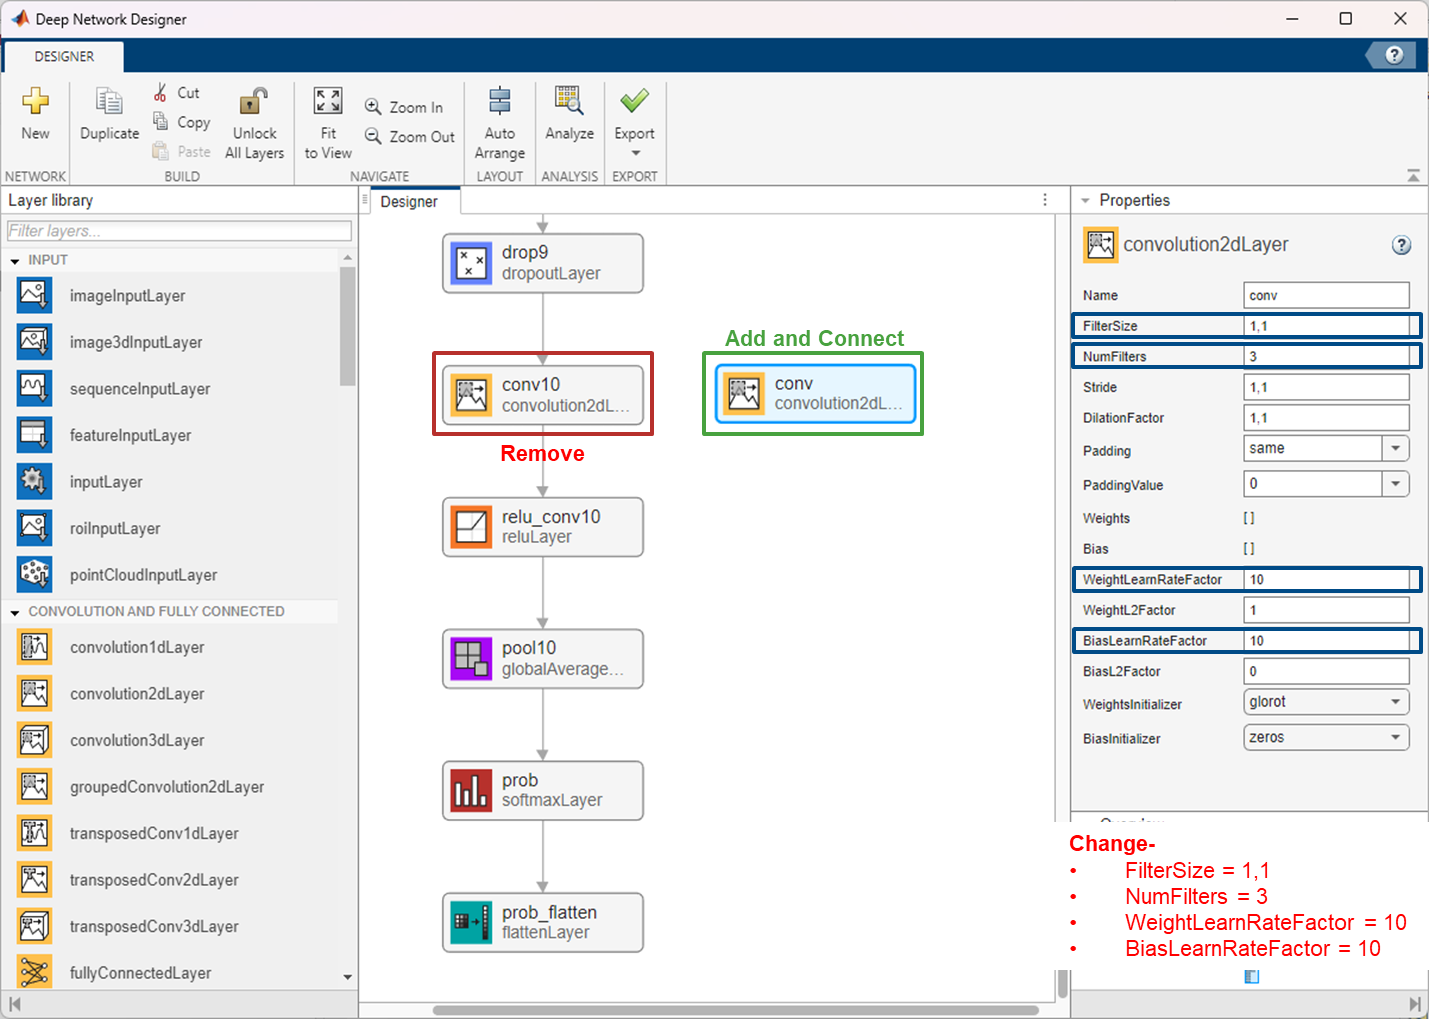

## **Step 3: Export network to workspace**

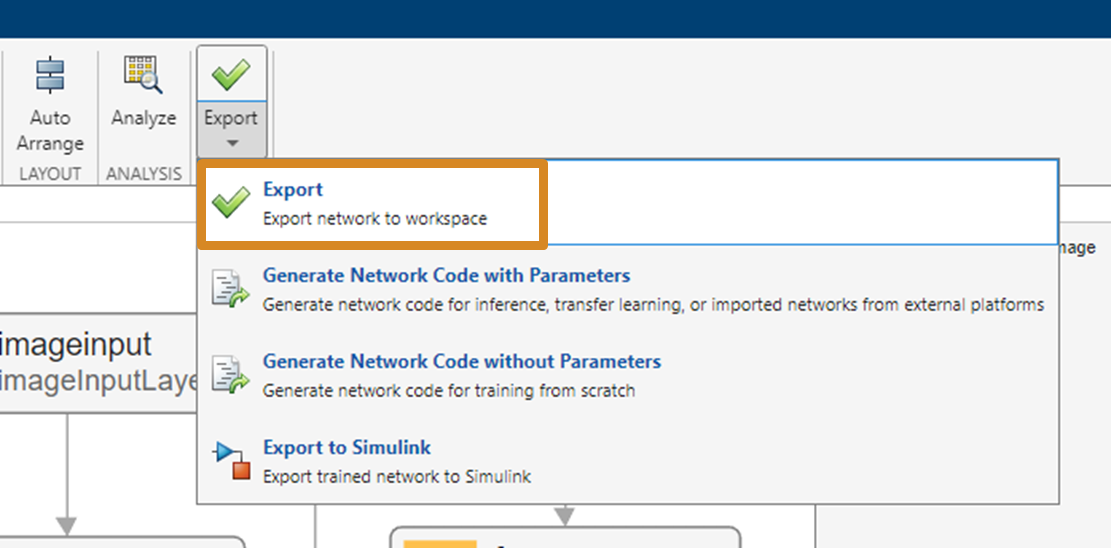

## Build CNN with Transfer Learning (programmatically)

net_1 = imagePretrainedNetwork("squeezenet");

Resize the images to fit the network we will build. 

inputSize = net_1.Layers(1).InputSize(1:2);
trainingImagesR = augmentedImageDatastore(inputSize, trainingImages);
testImagesR = augmentedImageDatastore(inputSize, testImages);

**Replace Final Layers**

The convolutional layers within the network are responsible for extracting features from images, which are then utilized by the final learnable layer for categorizing the input image. In SqueezeNet, for instance, the layer named 'conv10' plays a crucial role in merging the extracted features to predict class probabilities. To adapt a pretrained network for classifying a new set of images, it's essential to substitute this layer with new layers tailored to the new dataset.

Find the names of the layer to replace. 

net_1.Layers(end-5:end)

Typically, the last layer with learnable parameters in many networks is a fully connected layer. However, networks like SqueezeNet use a 1-by-1 convolutional layer as the last learnable layer. In such scenarios, it's necessary to replace this convolutional layer with a new one. 

The new layer should have a number of filters matching the number of new classes. To ensure the new layers learn at a faster rate compared to the pre-existing layers, it's recommended to increase the values of WeightLearnRateFactor and BiasLearnRateFactor for the convolutional layer.

classNames = categories(trainingImages.Labels);
numClasses = numel(classNames);
newConvLayer =  convolution2dLayer([1, 1],numClasses,'WeightLearnRateFactor',10,'BiasLearnRateFactor',10,"Name",'new_conv');
net_1 = replaceLayer(net_1,"conv10",newConvLayer);

net_1.Layers(end-5:end)

## Set Hyperparameters and Train Network

Use the following training options and save them to variable "options"

- InitialLearnRate = 0.0001

- MaxEpochs = 12

- MiniBatchSize = 10

- Plots = "training-progress"

- Metrics = "accuracy"

- Verbose = false

Check [Options for training deep learning neural network ](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html)for help

% InitialLearnRate = 
% MaxEpochs = 
% MiniBatchSize = 
% Plots = 
% Metrics = 
% Verbose = 

% ADD CODE HERE

options = trainingOptions("sgdm", ...
    'InitialLearnRate', InitialLearnRate, ...
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', MiniBatchSize, ...
    'Plots', Plots , ...
    'Metrics', Metrics , ...
    'Verbose', Verbose );




accuracy = 84.3750

% Make sure the name of network is same as the name of the network exported
% from Deep Network Designer
ECGNet = trainnet(trainingImagesR, net_1, "crossentropy",options); 

## Test the Network

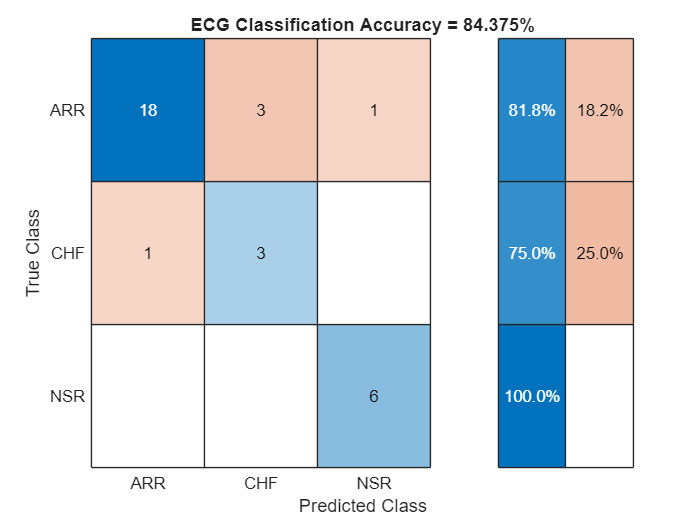

scores = minibatchpredict(ECGNet, testImagesR);


classNames = categories(trainingImages.Labels);
labels = scores2label(scores, classNames);

accuracy = testnet(ECGNet, testImagesR, "accuracy")

cm = confusionchart(labels, testImages.Labels);
figure
cm.RowSummary = 'row-normalized';
cm.Title = ['ECG Classification Accuracy = ' num2str(accuracy) '%'];

## Classify Signals using LSTM

Try out part 2 of the exercise.

edit Work_ECG_LSTM.mlx

*Copyright 2024 The MathWorks, Inc.*